# Subcycle Average for real-time simulation of very high PWM frequencies

Please make sure you are familiar with the concepts explained at [PMSM_Inverter_Guide](matlab:open('PMSM_Inverter_Guide')) about the standard Simscape to HDL workflow before starting this tutorial.

## Subcycle average concept

We will get back to the main model for desktop simulation to discuss how Subcycle Avarage (SCA) works.

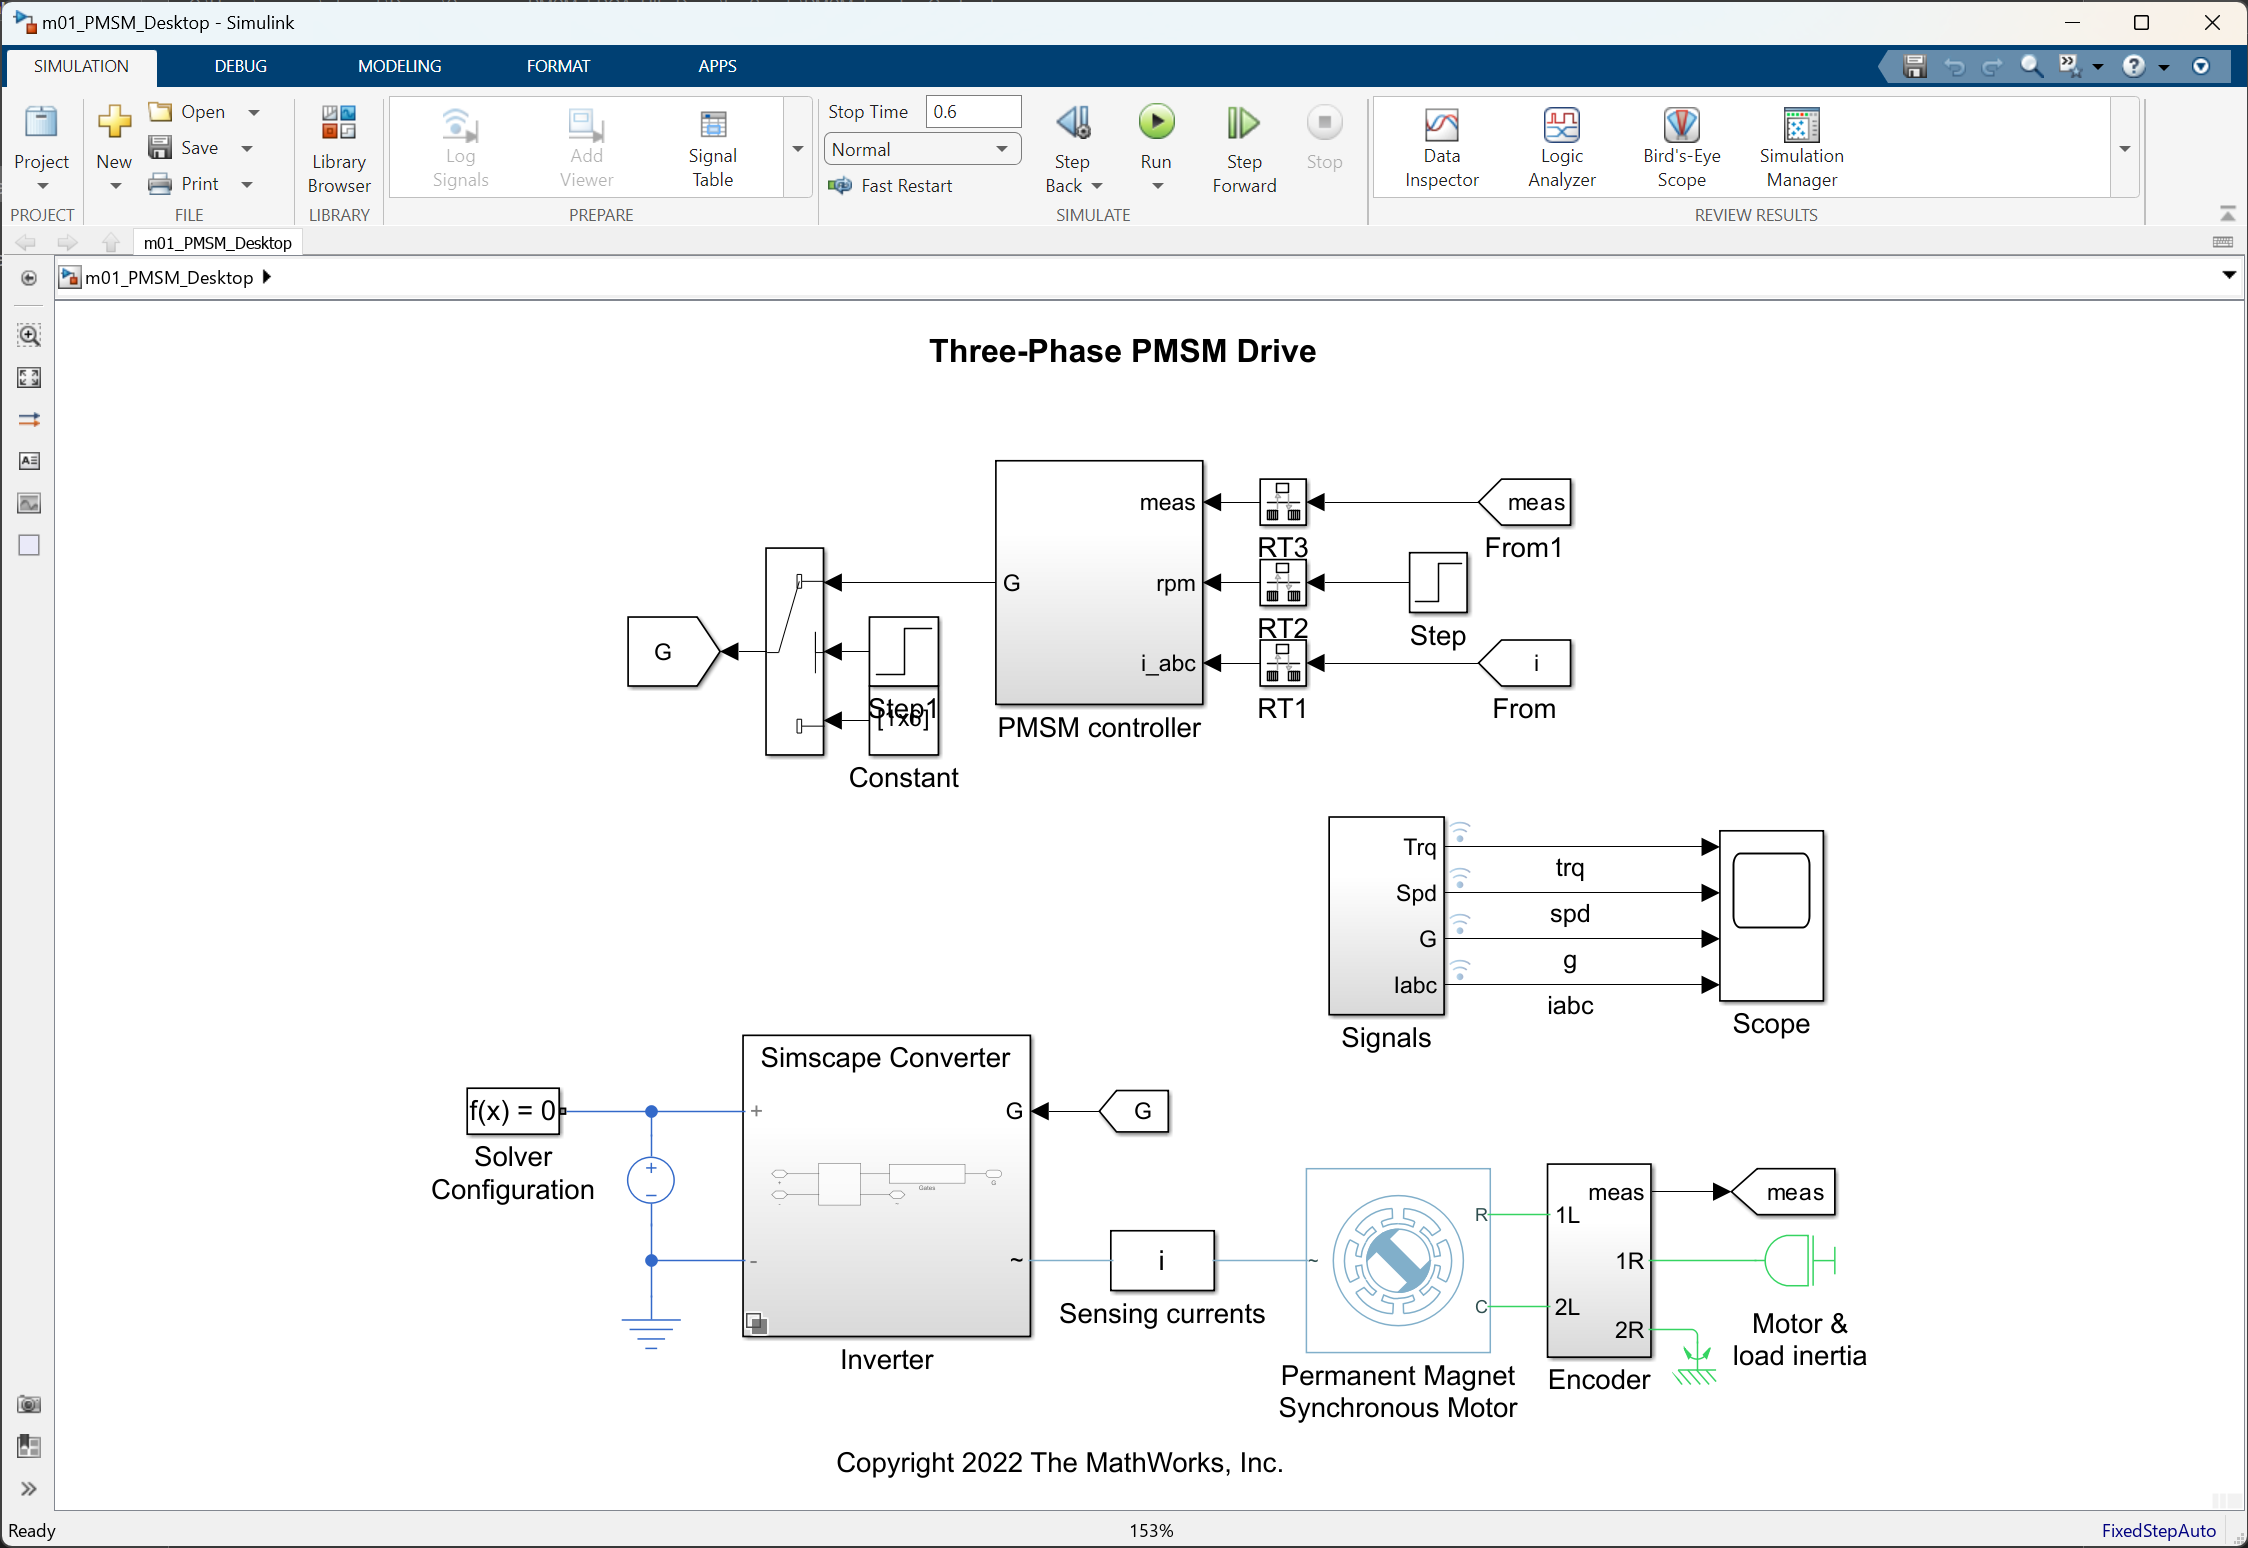

mdlDesktop = 'm01_PMSM_Desktop';
open_system(mdlDesktop);

Let's create a set of reference results based on the standard Pejovic approximation.

set_param([mdlDesktop,'/Solver Configuration'],'LocalSolverSampleTime','Ts');
set_param([mdlDesktop,'/Inverter'],'LabelModeActiveChoice','Pejovic');
simOutPej = sim(mdlDesktop);

Now, we can set a value fot the subcycle average factor greater than 1. This will allow us to simulate the Simscape network at a slower rate (by a factor equal to the SCA factor) without losing accuracy in the PWM sampling. In other words, we uncouple the PWM sampling that can have now any value between 0 and 1, of the plant model rate.

avgFactor = 10;
set_param([mdlDesktop,'/Solver Configuration'],'LocalSolverSampleTime',sprintf('Ts*%i',avgFactor));
set_param([mdlDesktop,'/Inverter'],'LabelModeActiveChoice','PejovicSCA');
simOutSCA = sim(mdlDesktop);

Please observe that the macroscopic numeric results are very similar to the ones obtained without averaging.

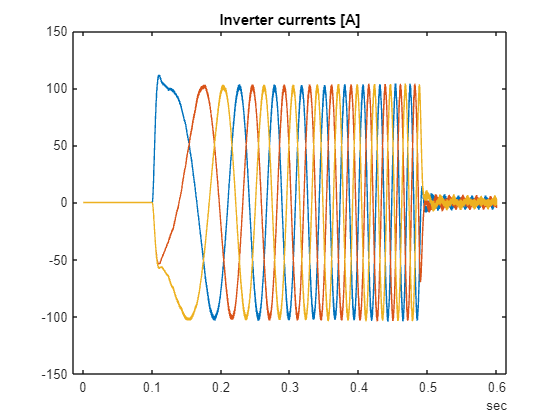

data = simOutSCA.logsout.getElement('iabc').extractTimetable;
plot(data.Time,data.Variables);
title('Inverter currents [A]');

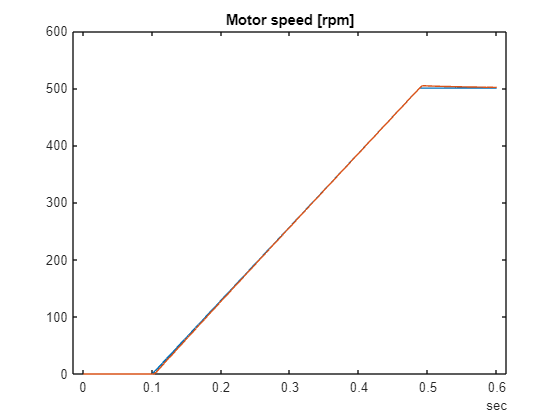

data = simOutSCA.logsout.getElement('spd').extractTimetable;
plot(data.Time,data.Variables);
title('Motor speed [rpm]');

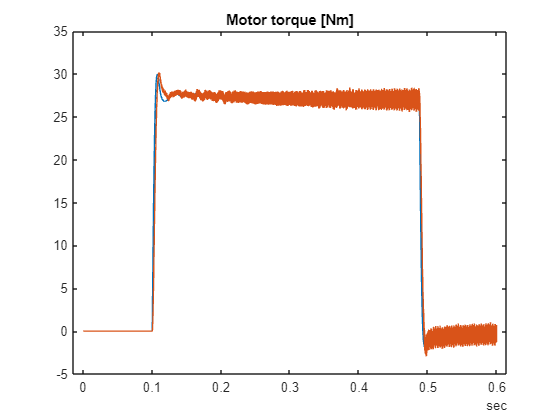

data = simOutSCA.logsout.getElement('trq').extractTimetable;
plot(data.Time,data.Variables);
title('Motor torque [Nm]');

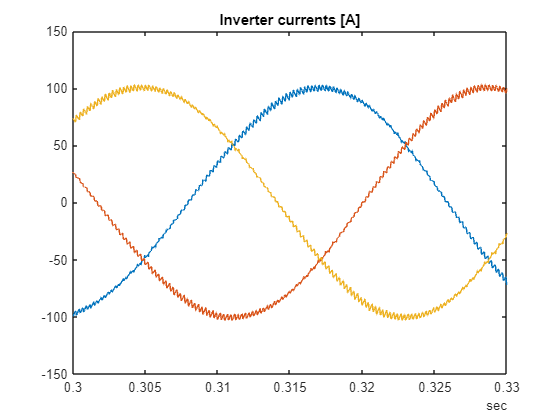

data = simOutSCA.logsout.getElement('iabc').extractTimetable;
plot(data.Time, data.iabc);
title('Inverter currents [A]');
xlim([duration(0,0,0.300) duration(0,0,0.33)]);

We can run another simulation but increasing the SCA factor from 10 to 100 for a more detailed comparison of the effects.

avgFactor = 100;
set_param([mdlDesktop,'/Solver Configuration'],'LocalSolverSampleTime',sprintf('Ts*%i',avgFactor));
set_param([mdlDesktop,'/Inverter'],'LabelModeActiveChoice','PejovicSCA');
simOutSCA_2 = sim(mdlDesktop);

We will compare all results and validate that the inverter current is very similar, allowing us to represent the dynamics of the system but with a plant model running at a sampling rate up to 100 times lower!

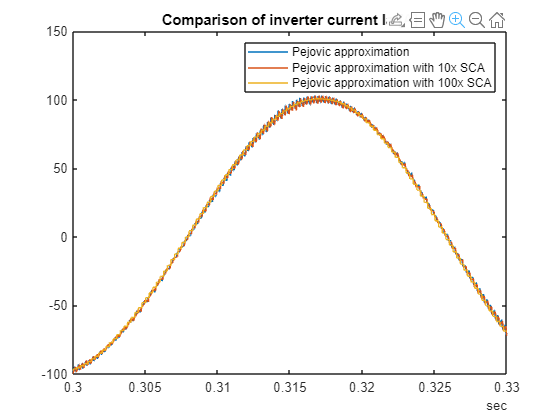

iabcPej = simOutPej.logsout.getElement('iabc').extractTimetable;
iabcSCA10 = simOutSCA.logsout.getElement('iabc').extractTimetable;
iabcSCA100 = simOutSCA_2.logsout.getElement('iabc').extractTimetable;
plot(iabcPej.Time, iabcPej.iabc(:,1),...
    iabcSCA10.Time, iabcSCA10.iabc(:,1),...
    iabcSCA100.Time, iabcSCA100.iabc(:,1));
title('Comparison of inverter current Ia [A]');
legend('Pejovic approximation','Pejovic approximation with 10x SCA','Pejovic approximation with 100x SCA');
xlim([duration(0,0,0.300) duration(0,0,0.33)]);

## Deploying Subcycle Average to FPGA

The Subcycle Average approach is also compatible with HDL code generation. This will enable us to design and build a very optimized FPGA implementation, which samples the PWM inputs at the same rate than the FPGA clock rate (~100MHz) while the state-space representation of the plant model runs at a slower model rate of ~1MHz as in the standard scenario without averaging.

mdlHdl = 'm02_PMSM_HDL';
open_system(mdlHdl);

We can use the same HDL-ready model than in the standard scenario but set a subcycle average factor greater than 1 to increase the PWM sampling rate allowing us to emulate even faster switching dynamics while being able to meet timing requirements when generating the FPGA bitstream.

avgFactor = 10;
Ts = 2.5e-7;
set_param(mdlHdl,'SimulationMode','accelerator');
simOutHdl = sim(mdlHdl);

As we have done in previous steps, we can plot the results and validate the FPGA source model before generating HDL code and the FPGA implementation.

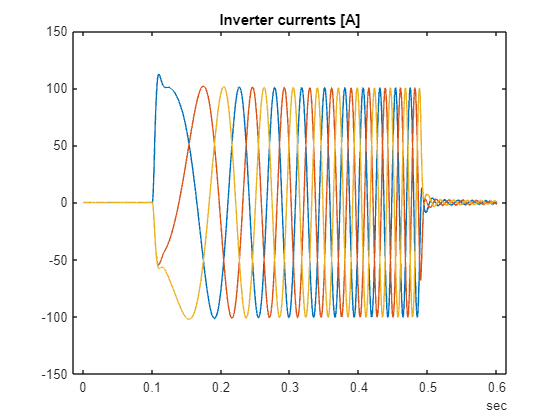

data = simOutHdl.logsout.getElement('iabc').extractTimetable;
plot(data.Time,data.Variables);
title('Inverter currents [A]');

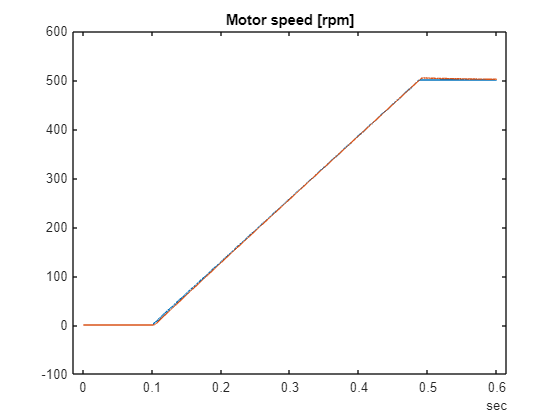

data = simOutHdl.logsout.getElement('spd').extractTimetable;
plot(data.Time,data.Variables);
title('Motor speed [rpm]');

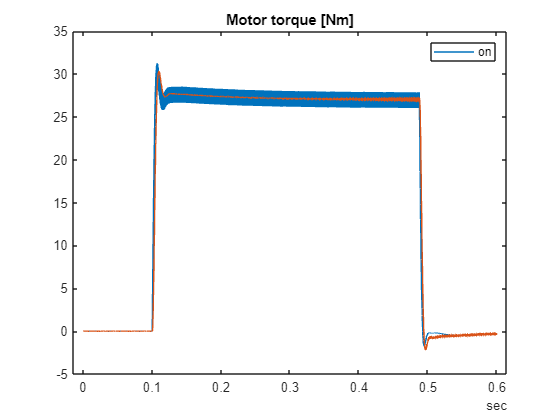

data = simOutHdl.logsout.getElement('trq').extractTimetable;
plot(data.Time,data.Variables);
title('Motor torque [Nm]');

After this last validation step, we can [open the HDL Workflow Advisor](matlab:hdladvisor([mdlHdl,'/FPGA Model']);) and use the same settings to generate a new FPGA bitstream, which will now sample PWM inputs at a faster rate enabling potentially more accurate representation of the switching dynamics.